# **Resistor Emulation**

This example shows you how to setup the IO921-12/10 I/O module, in order to verify the basic functionality of the [Resistor Control](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io92x_io97x_resistor_control) driver block.

The IO921 is a programmable resistor module with up to 18-channels of resistor chains. The flexible architecture allows the I/O module to be supplied in 8-bit, 12-bit, 16-bit or 24-bit resolution versions, for applications requiring finer resolution, greater resistance range, or higher channel count.

The driver block allows to select different variants of programmable resistor I/O modules. Any other type can be selected but you might need to adapt the model as the I/O modules have different number of channels, resolution and range of resistance.

The Simulink model features the [IO92X, IO970-IO973 - Resistor Control](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io92x_io97x_resistor_control) block.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO921-12/10 I/O module installed

- Connector cable from the I/O module to the terminal board

- 37-pin terminal board

- Ohmmeter

### Test Setup

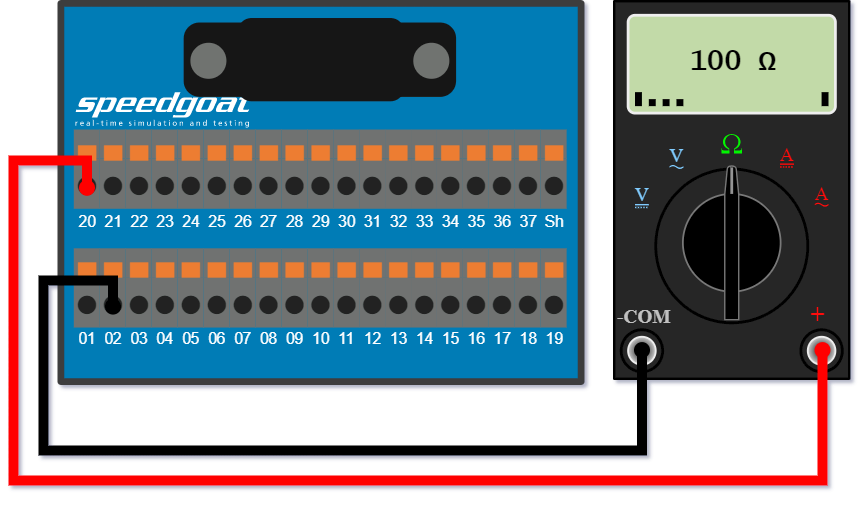

On the terminal board of the IO921 I/O module, connect a ohmmeter to one of the three enabled channels to measure the resistance as shown above. [IO921 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io92x_io97x_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_ResistorEmulation';
open_system(modelName);

### Model Description

In the model, a ramp signal is connected to channel one. With the first scope, the actual resistor value gets compared to the input signal. As the IO921 has a resolution of 1 Ohm, the resistance changes only on whole numbers.

On channel two, a step signal is connected which changes to zero ohms after 5 seconds. This represents a short circuit on channel two.

Channel three is used to show at which point the IO921 switches to the next higher resistance value as the resolution of the module is 1 Ohm.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the actual applied resistance values, check the scopes connected to the three enabled channels. In the first scope, a ramp signal must be displayed, and a step by step increasing signal (represented by the blue line). In the second scope, the step signal with a switching point at 5 seconds and a straight line at 100 Ohms must be displayed.

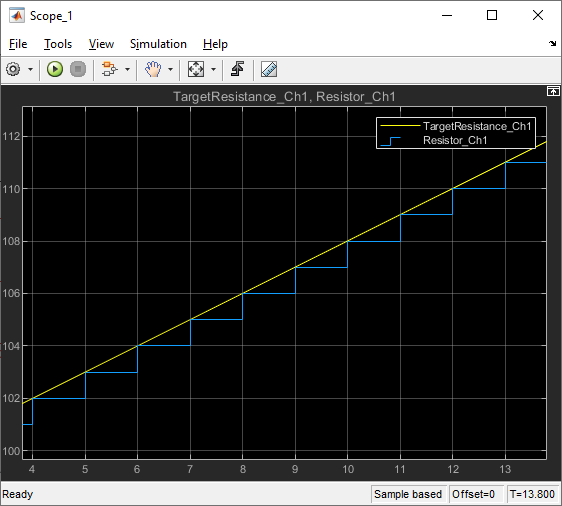

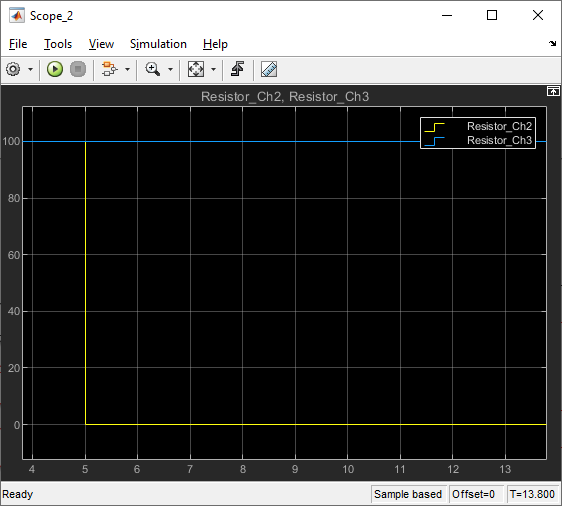

## Additional References

- [IO92x, IO97x documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io92x_io97x)